%Ackerman Steering  - ROBUST Controller

%Vehicle Parameters
m = 1500; %mass of the vehicle (kg)
Iz = 2250; %yaw Inertia
lf = 1.2;
lr = 1.6;
cf = 80e3; %cf cornering stiffness of front wheel
cr = 80e3; %cr cornering stiffness of rear wheel
Ux0 = 15; %nomial front speed



% Define the steering angle (delta) for the vehicle
delta = 0.1; % example steering angle in radians

% Calculate the vehicle's dynamics parameters
alpha_f = atan((lr / lf) * tan(delta)); % front slip angle
alpha_r = atan((lf / lr) * tan(delta)); % rear slip angle

% Calculate lateral forces at the front and rear wheels
Fyf = cf * alpha_f; % lateral force at the front
Fyr = cr * alpha_r; % lateral force at the rear
disp('lateral force at the front');

lateral force at the front


disp(Fyf);

   1.0639e+04



disp('lateral force at the rear');

lateral force at the rear


disp(Fyr);

   6.0088e+03




% Calculate the total lateral force acting on the vehicle
F_total = Fyf + Fyr;
disp('Total force');

Total force


disp(F_total);

   1.6648e+04




% Calculate the yaw rate (r) using the lateral forces and vehicle parameters
r = (F_total * (lf - lr)) / Iz;
disp('Yaw rate:');

Yaw rate:


disp(r);

   -2.9596




%Build state space matrices for nominal operating point
[A0 , B0] = lateral_dynamics_matrix(m, Iz, lf, lr, cf, cr, Ux0);

%LQR Design 
%Staes; [vy,r,ey,eps]
%we want ey and eys to be  small(heading error)
Q = diag([10 , 1 , 50 , 10]);
R = 1; %steering effort weight

K = lqr(A0,B0,Q,R); %gain vector

disp("--------------------------")

--------------------------


disp('LQR gain K(delta = -K *x):');

LQR gain K(delta = -K *x):


disp(K);

    0.5139    3.5918    7.0711   34.5554



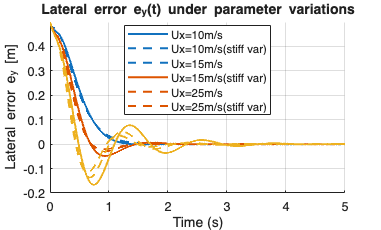


Acl_nom = A0 -B0 *K;%closed loop matrix

%intial Condition : Lateral error 0.5 , others zero
x0 = [0;0;0.5;0];
tspan = [0,5];
odefun_nom = @(t, x)Acl_nom *x;
[t_nom,x_nom] = ode45(odefun_nom,tspan,x0);
ey_nom = x_nom(:,3);
eps_nom = x_nom(:,4);
vy_nom = x_nom(:,1);
r_nom = x_nom(:,2);

%robustness Test : VArying the speed and controlling the stiffness
speeds = [10 ,15 ,25];
stiff_scale = [0.7 ,1.0 ,1.3];

colors = lines(length(speeds));

figure;hold on; grid on;
title('Lateral error e_y(t) under parameter variations');
xlabel('Time (s)');
ylabel('Lateral error e_y [m]');

for i=1:length(speeds)
    Ux = speeds(i);

    for j=1:length(stiff_scale)
        scale = stiff_scale(j);
        cf_var = cf * scale;
        cr_var = cr * scale;

        [Avar , Bvar] = lateral_dynamics_matrix(m,Iz,lf, lr,cf_var,cr_var,Ux );
        Acl_var = Avar -Bvar* K;

        odefun_var = @(t, x)Acl_var * x;
        [t_var, x_var]=ode45(odefun_var,tspan,x0);

        if j==1
            plot(t_var,x_var(:,3), 'Color',colors(i,:), 'LineWidth',1.5);
        else
            plot(t_var, x_var(:,3), 'Color', colors(i,:), 'LineWidth', 1.5, 'LineStyle', '--');
        end
    end
end
legend('Ux=10m/s','Ux=10m/s(stiff var)','Ux=15m/s','Ux=15m/s(stiff var)','Ux=25m/s','Ux=25m/s(stiff var)','Location','best');

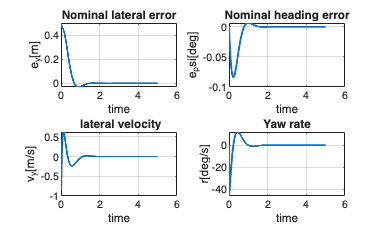


figure;
subplot(2,2,1);plot(t_nom,ey_nom,'LineWidth',1.5);grid on;
xlabel('time');ylabel('e_y[m]');title('Nominal lateral error');

subplot(2,2,2);plot(t_nom,eps_nom,'LineWidth',1.5);grid on;
xlabel('time');ylabel('e_psi[deg]');title('Nominal heading error');

subplot(2,2,3);plot(t_nom,vy_nom,'LineWidth',1.5);grid on;
xlabel('time');ylabel('v_y[m/s]');title(' lateral velocity');

subplot(2,2,4);plot(t_nom,r_nom * 180/pi,'LineWidth',1.5);grid on;
xlabel('time');ylabel('r[deg/s]');title('Yaw rate');

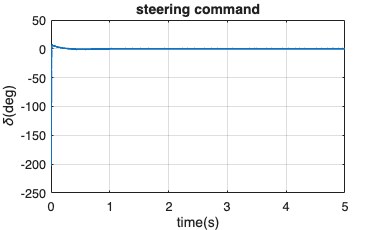


delta_nom = -(K * x_nom.').';

figure;
plot(t_nom,delta_nom*180/pi, 'LineWidth',1.5);grid on;
xlabel('time(s)');ylabel('\delta(deg)');
title('steering command');


function [A,B]= lateral_dynamics_matrix(m, Iz, lf, lr, cf, cr, Ux)

    A = zeros(4,4);
    B = zeros(4,1);

    A(1,1) = (-2*cf/Ux - 2*cr/Ux)/m;
    A(1,2) = (-2*cf*lf/Ux + 2*cr*lr/Ux -m*Ux)/m;
    A(2,1) = (-2*cf*lf/Ux + 2*cr*lr/Ux)/Iz;
    A(2,2) = (-2*cf*lf^2/Ux + 2*cr*lr^2/Ux)/Iz;
    A(3,1) = 1;
    A(3,4) = Ux;
    A(4,2) = 1;

    B(1,1) = 2*cf/m;
    B(2,1) = 2*cf*lf/Iz;
end




